# Example 5

#### Problem OCP (Brachistochrone):


$$\min_{{y}(t)} \int_a^b \frac{\sqrt{1+(y^\prime (x))^2}}{\sqrt{2gy(x)}}dx$$


subject to:


$${y}(a)=0, \quad y(b)=h $$


## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 50;
CONSTANTS.h = 1;

### Initial Guess

N = CONSTANTS.N; 
%y = linspace(0,CONSTANTS.h,N+1)';
y = ones(N+1,1);
x0 = y;

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 1.853624 seconds.


### Plot

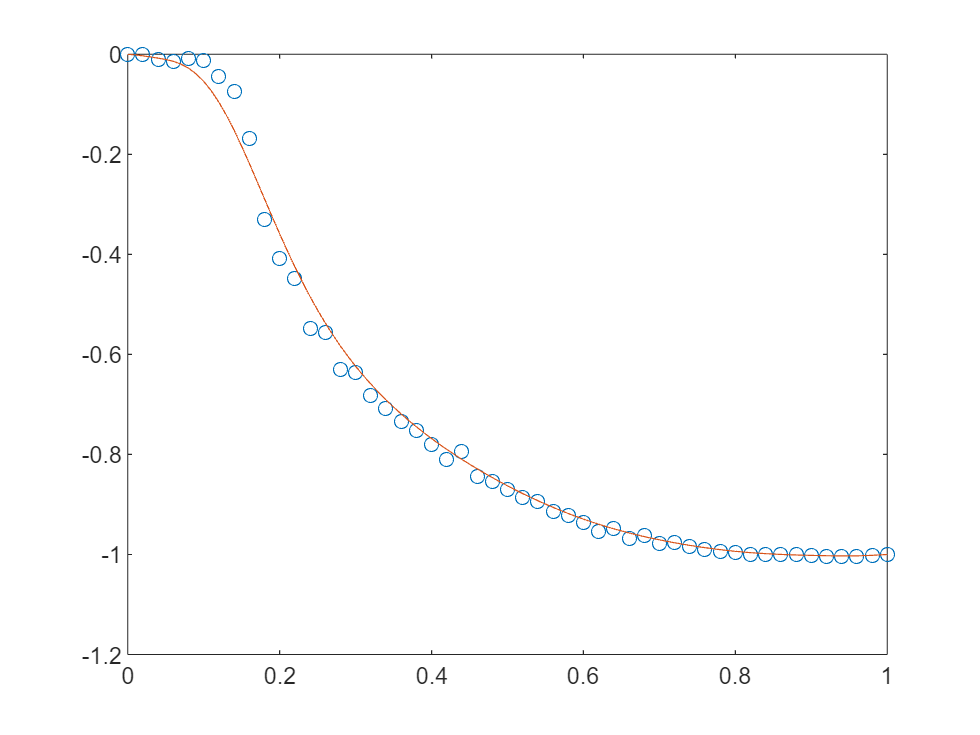

N = CONSTANTS.N;
[tnodes,w,Diff] = BeBOT(CONSTANTS.N,1);
y = x(1:N+1);

t = 0:0.01:1;

figure
plot(tnodes,-y,'o'); hold on
plot(t,-BernsteinPoly(y,t));

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 
y = x(1:N+1);
[tnodes,w,Diff] = BeBOT(CONSTANTS.N,1);
yprime = (y'*Diff)';

J = w'*(sqrt(1+yprime.*yprime)./sqrt(2*10*y));
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

y = x(1:N+1);

c=[];
ceq=[y(1)-0; y(end) - CONSTANTS.h];
end